# **Self-Referential Processing in Neuronal Populations of Ventromedial and Orbitofrontal Cortex** 

% -*- UFT -*-
% Author: behira
% behzadiravani@gmail.com
% loading the data
clc
clear 
data = readtable('data\stimlock.tsv', FileType='text'); % reading that tabular data

## Subject and Experimental Condition

% create report object 
report = stat_report(data, 'data\BHV.json', 'data\FrontalEcogvsSeeg.json'); % stat_report instance
% print some info
Uniq_id = report.report("num_indiv");

The total number of pt is: 22

 

report.report("number_total_elec"); % statistical summary of number of electrodes

The total number of elec is: 253, in total patients 22
 mean (std) # elec: 11.50(10.60), range =  [1,38]

 

## Behavioral Data

Finding out how many trails per conditions have been performed on average. 

report.report("number_trials"); % statistical summary of number of trials per condition 

EP # trails: mean (std): 24 (1.2)
SJ # trails: mean (std): 24 (1.9)
MTH # trails: mean (std): 39 (1.7)


report.report("number_true_false") % statistical summary of number of trials responded with true and false

EP true # trails replied with true: mean (std): 9 (4), range = [4,22]
EP false # trails replied with true: mean (std): 15 (4), range = [4,21]
SJ true # trails replied with true: mean (std): 16 (3), range = [8,23]
SJ false # trails replied with true: mean (std): 8 (3), range = [3,14]
MTH true # trails replied with true: mean (std): 21 (4), range = [15,31]
MTH false # trails replied with true: mean (std): 16 (3), range = [9,20]


ans = struct with fields:
     true: {[9 4 4 22]  [16 3 8 23]  [21 4 15 31]}
    false: {[15 4 4 21]  [8 3 3 14]  [16 3 9 20]}


report.report("reaction_time") % statistical summary of RT responded with true and false

EP true RT replied with true: mean (std): 3.67 (1.40), range = [1.35,6.48]
EP false RT replied with true: mean (std): 3.62 (1.40), range = [1.38,6.45]
SJ true RT replied with true: mean (std): 3.06 (1.33), range = [0.96,5.49]
SJ false RT replied with true: mean (std): 3.56 (1.27), range = [1.16,5.86]
MTH true RT replied with true: mean (std): 4.65 (1.84), range = [1.22,8.32]
MTH false RT replied with true: mean (std): 5.37 (2.04), range = [1.34,9.47]


ans = struct with fields:
     true: {[3.6700 1.4000 1.3500 6.4800]  [3.0600 1.3300 0.9600 5.4900]  [4.6500 1.8400 1.2200 8.3200]}
    false: {[3.6200 1.4000 1.3800 6.4500]  [3.5600 1.2700 1.1600 5.8600]  [5.3700 2.0400 1.3400 9.4700]}


report.report("veridicality") % statistical summary of response veridicality.

EP true veridicality replied with true: mean (std): 0.47 (0.15), range = [0.24,0.82]
EP false veridicality replied with true: mean (std): 0.70 (0.21), range = [0.11,0.96]
MTH true veridicality replied with true: mean (std): 0.87 (0.11), range = [0.60,1.00]
MTH false veridicality replied with true: mean (std): 0.79 (0.20), range = [0.29,1.00]


ans = struct with fields:
     true: {[0.4700 0.1500 0.2400 0.8200]  [0.8700 0.1100 0.6000 1]}
    false: {[0.7000 0.2100 0.1100 0.9600]  [0.7900 0.2000 0.2900 1]}


## Self-Referential Neuronal Population Activity in the OFC and vmPFC 

report.report("ECoGSEEG") % statisitcal summary of number of ECoG and SEEG electrodes as well as OFC and vmPFC(MPFC)

S01 -- electype: ECOG
S02 -- electype: ECOG
S03 -- electype: ECOG
S04 -- electype: ECOG
S05 -- electype: ECOG
S06 -- electype: ECOG
S07 -- electype: ECOG
S08 -- electype: ECOG
S09 -- electype: ECOG
S10 -- electype: ECOG
S11 -- electype: ECOG
S12 -- electype: ECOG
S13 -- electype: ECOG
S14 -- electype: ECOG
S15 -- electype: ECOG
S16 -- electype: ECOG
S17 -- electype: SEEG
S18 -- electype: ECOG
S19 -- electype: SEEG
S20 -- electype: ECOG
S21 -- electype: SEEG
S22 -- electype: SEEG
ECOG = 13 +/- 11, [2, 38]
OFC = 0.76 +/- 0.33
MPFC = 0.24 +/- 0.33
SEEG = 6 +/- 6, [1, 13]
OFC = 0.50 +/- 0.58
MPFC = 0.50 +/- 0.58


Assessing the spatial distribution of self-referntial- and math-activated electrodes on the cortex. The significance has been determined by 5000 permutations Monte Carlo test and stored in Pval_LOC in the data table. 

Starting parallel pool (parpool) using the 'local' profile ...


Connected to the parallel pool (number of workers: 8).
observation 1 of 107
observation 14 of 107
observation 13 of 107
observation 12 of 107
observation 11 of 107
observation 10 of 107
observation 9 of 107
observation 2 of 107
observation 20 of 107
observation 19 of 107
observation 18 of 107
observation 17 of 107
observation 16 of 107
observation 15 of 107
observation 3 of 107
observation 26 of 107
observation 25 of 107
observation 24 of 107
observation 23 of 107
observation 22 of 107
observation 21 of 107
observation 4 of 107
observation 32 of 107
observation 31 of 107
observation 30 of 107
observation 29 of 107
observation 28 of 107
observation 27 of 107
observation 5 of 107
observation 6 of 107
observation 44 of 107
observation 43 of 107
observation 42 of 107
observation 41 of 107
observation 40 of 107
observation 39 of 107
observation 7 of 107
observation 50 of 107
observation 49 of 107
observation 48 of 107
observation 47 of 107
observation 46 of 107
observation 45 of 107
observa

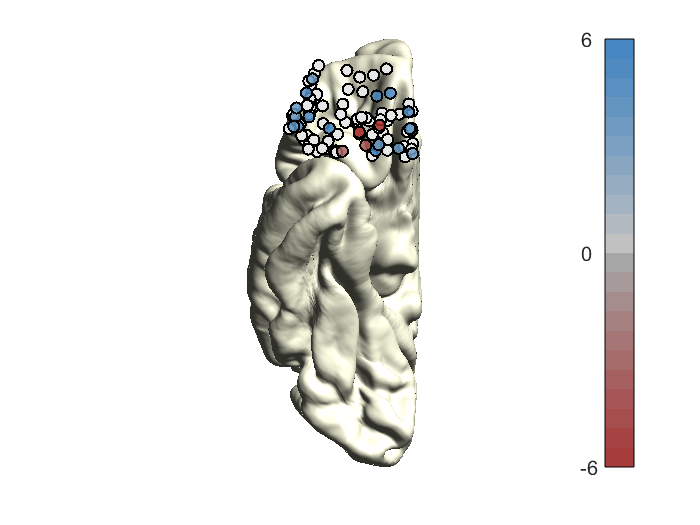

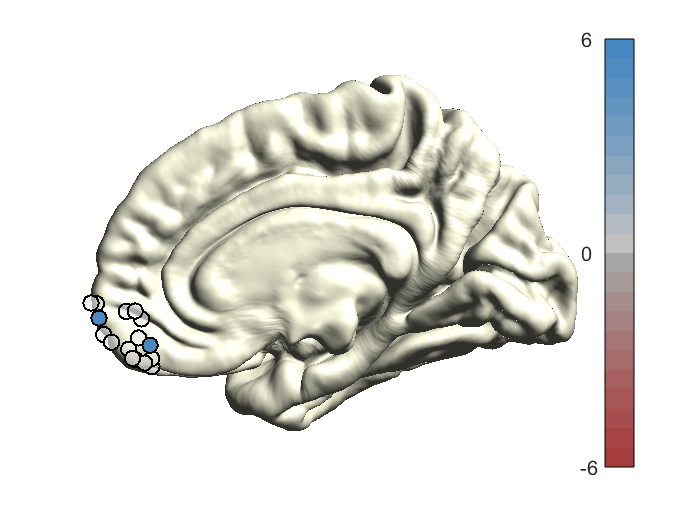

observation 1 of 146
observation 2 of 146
observation 3 of 146
observation 4 of 146
observation 5 of 146
observation 6 of 146
observation 7 of 146
observation 8 of 146
observation 17 of 146
observation 16 of 146
observation 15 of 146
observation 14 of 146
observation 13 of 146
observation 12 of 146
observation 11 of 146
observation 10 of 146
observation 9 of 146
observation 100 of 146
observation 99 of 146
observation 98 of 146
observation 97 of 146
observation 116 of 146
observation 115 of 146
observation 132 of 146
observation 142 of 146
observation 26 of 146
observation 25 of 146
observation 24 of 146
observation 23 of 146
observation 22 of 146
observation 21 of 146
observation 20 of 146
observation 19 of 146
observation 18 of 146
observation 104 of 146
observation 103 of 146
observation 102 of 146
observation 101 of 146
observation 122 of 146
observation 121 of 146
observation 133 of 146
observation 139 of 146
observation 146 of 146
observation 35 of 146
observation 34 of 146
obser

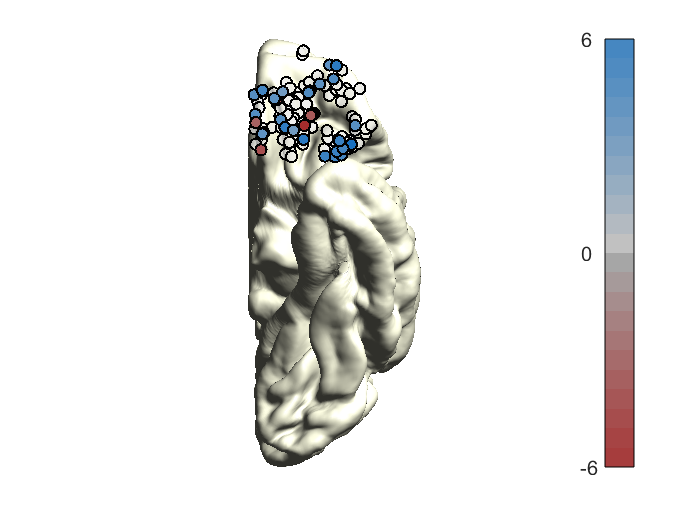

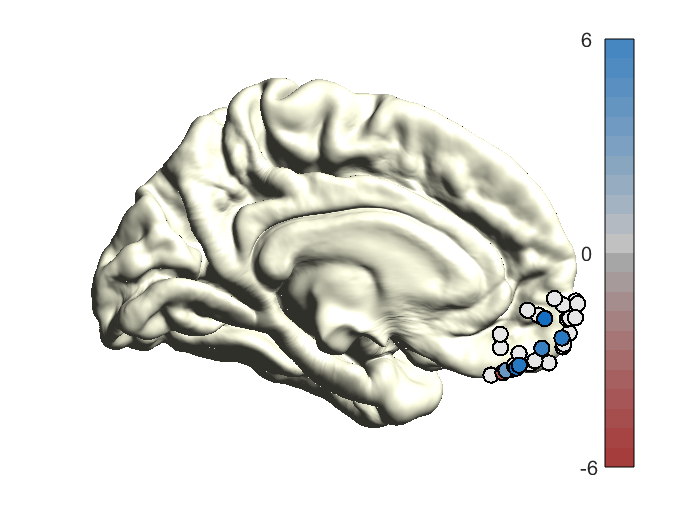

R = resultiEEG(data, 'data\BHV.json', 'data\FrontalEcogvsSeeg.json'); % cerate an instance of resultiEEG object 
% define the colors for electrode activity in hex
col = ["#0065C1",... blue for self-referential 
        "#A63838" ]; % red for math 
R.LocalizeSelfMath(col);

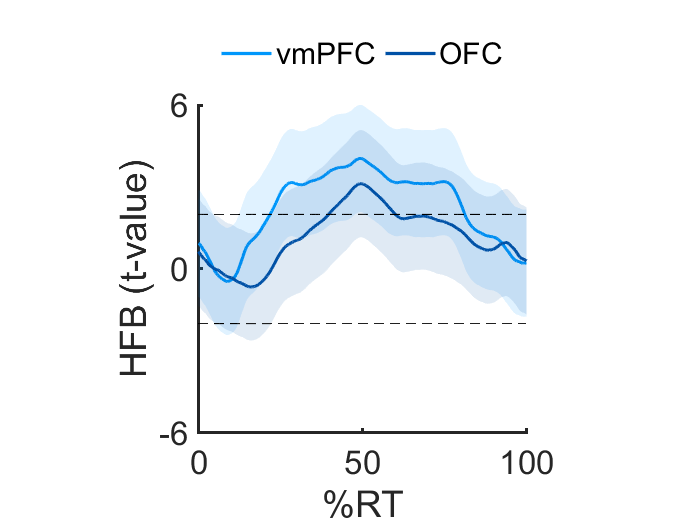

{
  "Anatomy": [
    "MPFC",
    "OFC"
  ],
  "time": [
    22,
    40
  ],
  "tvalue": [
    2.0582317462587456,
    2.0515793356025762
  ],
  "dof": [
    38,
    207
  ],
  "pvalue": [
    0.046473355236149594,
    0.041469574463316672
  ],
  "CI": [
    [
      -0.00061970406647422066,
      0.0193729430359345
    ],
    [
      0.00017573612611216163,
      0.017472824648551242
    ]
  ]
}


% read the time warped HFB envelope
HFB_tw.data  = R.getTimeWarppedHFB('data\Stimlock-TimeWarped_ieeg.dat');
% read labels 
HFB_tw.label = readtable('data\Stimlock-TimeWarped.tsv', FileType = 'text');
% trials were warped to 0:100% of RT 
HFB_tw.time  = (0:size(HFB_tw.data,2)-1)./512 - .5; % pre = 500ms, fsamp = 512
% define colors 
col = ["#0097FB", "#0051A6"]; % light and dark blue 
R.plot_HFB(HFB_tw, .1, col) % smoothing .1s 

Testing if in the same brain a pattern similar to gourp level can be found. Therefore, we need to first find individuals with electrode implanted both in OFC and vmPFC. 

[SE, SJ] = R.find_sameBrain(HFB_tw.label, HFB_tw.data, HFB_tw.time); % finds data from same brains
t2p = time2peak(SE, SJ) % create time2peak object 
t

Now we assess how many percenatges of the electrodes were activated during self-referential vs. math.

out = report.report("active_total"); % how many electrodes were activated per each condition: self > math -> self, self < math -> math, self = math -> not selective  
fprintf('total of %1.0f(%1.0f)%% self-activated\n', mean(cellfun(@(x) x.self, out))*1e2, std(cellfun(@(x) x.self, out))*1e2)

total of 13(15)% self-activated


fprintf('total of %1.0f(%1.0f)%% math\n', mean(cellfun(@(x) x.math, out))*1e2, std(cellfun(@(x) x.math, out))*1e2)

total of 4(5)% math


Performing a paried t-test to indicate if the difference between the percentage of self- vs. math-activated electrodes are statistically meaningful. 

% calculate two-ways, paired ttest to compare the percentages of self- vs. math-activated electrodes  
[~, p, CI, stat ] = ttest(cellfun(@(x) x.self, out), cellfun(@(x) x.math, out));
fprintf('self > math: t(%d) = %1.2f, p < %1.2f, CI = [%1.2f, %1.2f]', stat.df, stat.tstat, p, CI)

self > math: t(21) = 2.80, p < 0.01, CI = [0.02, 0.16]

We further assess if the self-episodic and self-judgment electrodes within the self-referentally activated populations overlaps. 

out = report.report("percentage");
fprintf('total of %1.0f(%1.0f)%% within self-referental populations weer activated both in EP(SE) and SJ\n', nanmean(cell2mat(out.both))*1e2, nanstd(cell2mat(out.both))*1e2)

total of 3(7)% within self-referental populations weer activated both in EP(SE) and SJ


A little anatomical overlap found betweem self-episodic and self-judgment within self-referentailly activated populations.

### Performing a linear-mixed effect model (LMM) to follow up if HFB differes for SE and SJ